# Lab 6

## Kurt Delegard

## PHYS 434 AB

### Time spent drafting: 

clear;
load('hera_data.mat')

Again, we will be working with data from the Hydrogen Epoch of Reionization Array ([HERA](https://reionization.org)) project. For review:

The dataset named 'visdata' is an array with dimensions 4x1024x1x82680. These dimensions correspond to:

- 4 different polarizations of light (XX, YY, XY, YX).

- 1024 different frequencies between 100 and 200 Mhz

- 1 spectral window (This data is irrelevant to our analysis)

- 82680 = (baseline pairs * times). This axis can be thought of as a column vector of data from every baseline pair for time t=1, vertically concantenated with a column vector of data from every baseline pair for time t=2, 3, 4.... etc.

Note: time is given in units of Julian days, as demonstrated [here](http://reionization.org/manual_uploads/HERA069_IDR2.2_Memo_v2.html). The time t=1 corresponds to the first 1,378 entries in the array time_array from the data file:

time_1 = time_array(1);
fprintf('%.6f\n', time_1)

2458108.125574


We are interested in defining the background for this experiment; that is, we would like to define a set of signal-free data. We start with the set of data from all baselines at a specific instant in time. HERA observes 4 different polarizations of light at once, so we can take the average of the data from all 4 polarizations:

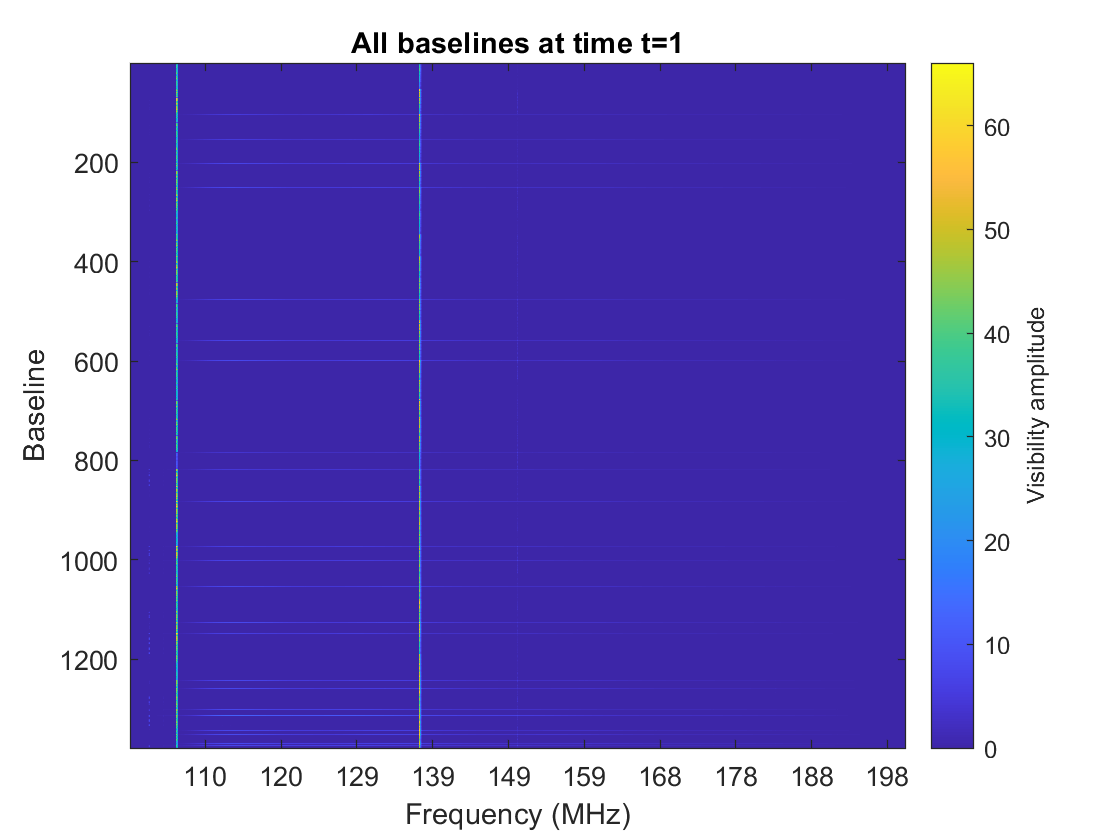

pol = 1:4;
range = 1:1378;
visdata_re = visdata.r(pol, :, 1, range);
visdata_im = visdata.i(pol, :, 1, range);
visdata_magnitude = sqrt(visdata_re.^2 + visdata_im.^2);
visdata_time1 = sum(visdata_magnitude(:, :, 1, range), 1)./4;

clf;
imagesc(squeeze(visdata_time1)')
xt = get(gca, 'XTick');
set(gca, 'XTick', xt, 'XTickLabel', round(xt/10.24 + 100));
xlabel('Frequency (MHz)');
ylabel('Baseline')
c = colorbar;
c.Label.String = "Visibility amplitude";
title('All baselines at time t=1')

We can remove these horizontal streaks of data, which correspond to baselines comprised of one antenna being correlated with itself.

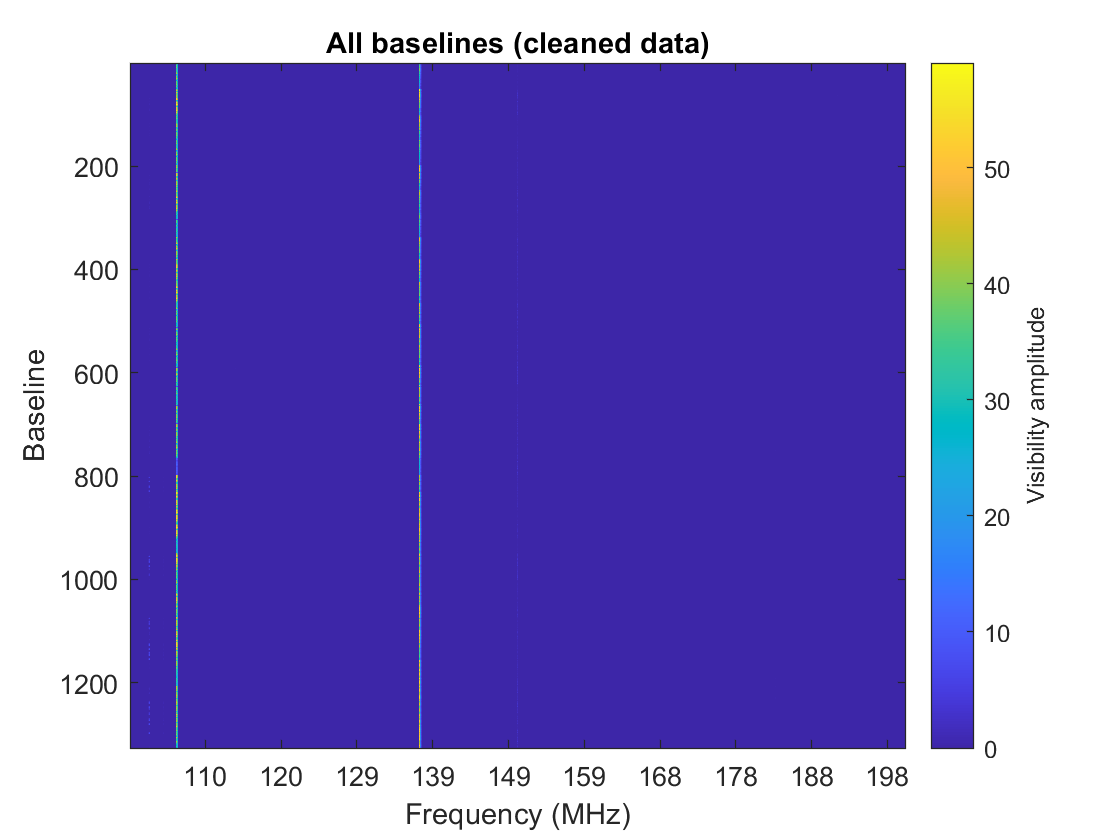

commonpair_indices = baselines(:, 1) == baselines(:, 2);
clean_data = visdata_time1(:, :, :, ~commonpair_indices);
clean_img = squeeze(clean_data)';
clf;
imagesc(clean_img);
xt = get(gca, 'XTick');
set(gca, 'XTick', xt, 'XTickLabel', round(xt/10.24 + 100));
xlabel('Frequency (MHz)');
ylabel('Baseline')
c = colorbar;
c.Label.String = "Visibility amplitude";
title('All baselines (cleaned data)')

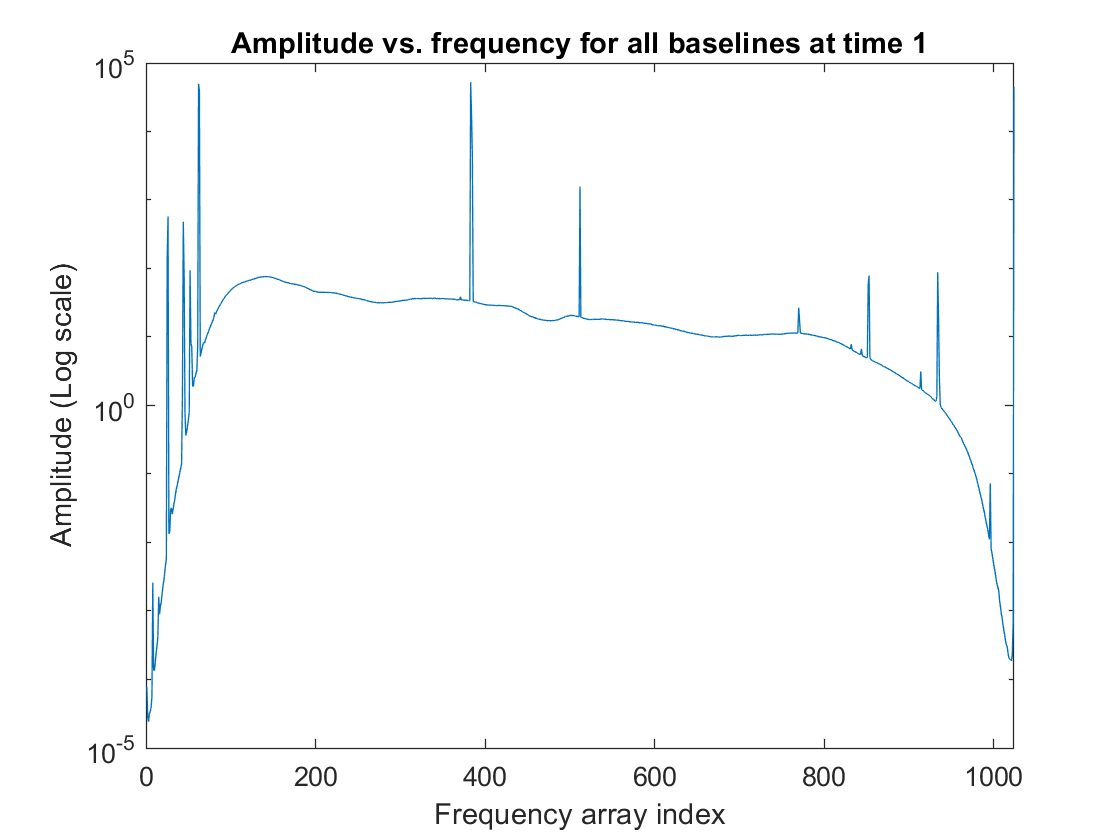

litude1 = squeeze(sum(clean_img, 1));
clf;
semilogy(1:1024, amplitude1(1:1024))
xlim([0 1024])
xlabel('Frequency array index');
ylabel('Amplitude (Log scale)')
title('Amplitude vs. frequency for all baselines at time 1')

The region of the most steady background is the flat middle region of this plot, ranging from indices ~180 to ~800 in the array of frequencies.

%Answers in MHz
freq_i = freq_array(180) ./ 1e6

freq_i = 117.4805

freq_f = freq_array(800) ./ 1e6

freq_f = 178.0273

We would like to fit a statistical model to a histogram of our data. This will help us analyze the overall trend of the data and predict the significance of certain signal strengths.

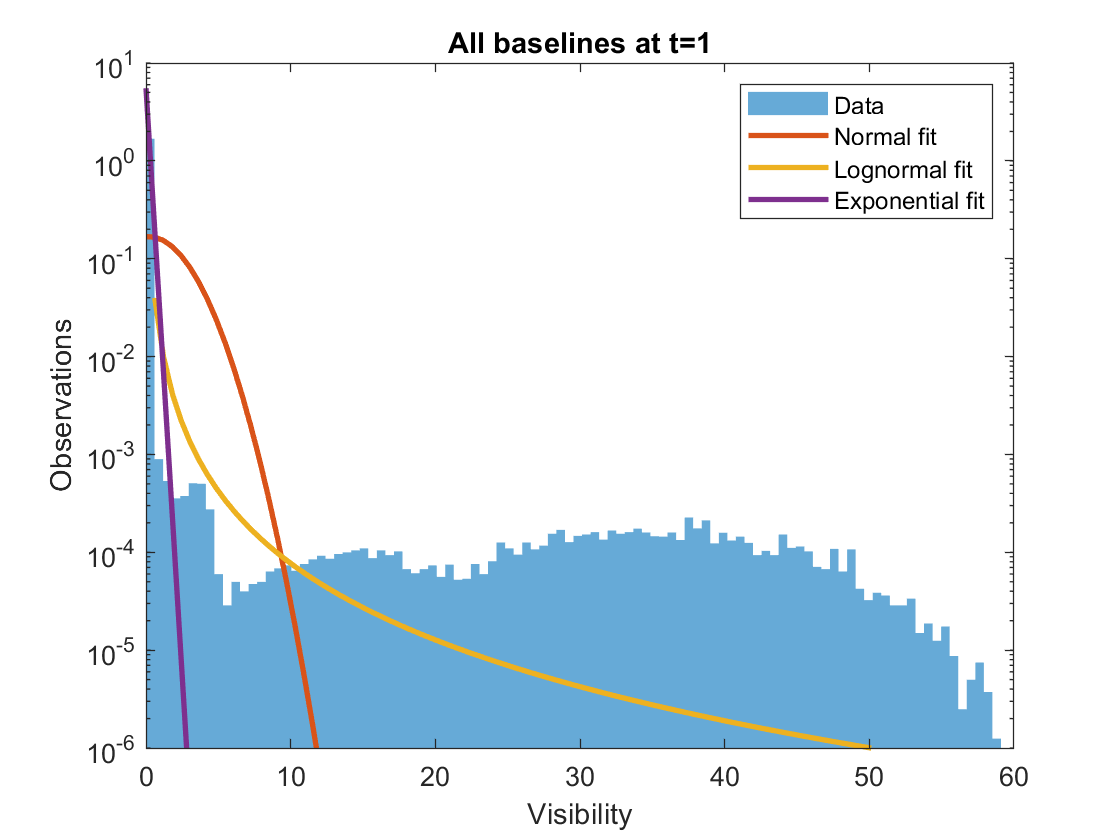

clf;
histogram(clean_img, 100, 'EdgeColor',"none", 'Normalization', 'pdf'), hold on;
clean_img_v = reshape(clean_img(clean_img > 0), 1, [])';

PDnorm = fitdist(clean_img_v, 'Normal');
PDlogn = fitdist(clean_img_v, 'Lognormal');
PDexp = fitdist(clean_img_v, 'Exponential');

xs = linspace(0, 60, 100);
norm_ys = normpdf(xs, PDnorm.mu, PDnorm.sigma);
logn_ys = lognpdf(xs, PDlogn.mu, PDlogn.sigma);
exp_ys = exppdf(xs, PDexp.mu);
plot(xs, [norm_ys; logn_ys; exp_ys], 'linewidth', 2);
set(gca, 'YScale', 'log')
xlim([0 60])
ylim([1e-6, 10])
ylabel('Observations')
xlabel('Visibility')
title('All baselines at t=1')
legend('Data', 'Normal fit', 'Lognormal fit', 'Exponential fit')

Unfortunately, it seems that no particular model would accurately fit to our data. Above are three examples of possible distributions which have their parameters set to most accurately fit the data as determined by MATLAB. In reality, this data is far too unpredictable and noisy to be described by a single statistical distribution.

By limiting the background data we look at, we can observe the trend for a subset of the data above. We can cut out the highly-varying data at the extreme ends of the frequency spectra. By doing this, we limit ourselves to look at data from the semi-stable region of background observed in the plot above of amplitude vs. frequency. Furthermore, we can limit ourselves to look at very low visibility amplitudes, since the spikes on the amplitude plot (likely corresponding to frequencies used for Earth-space communications) are anomalies that we can define and filter out.

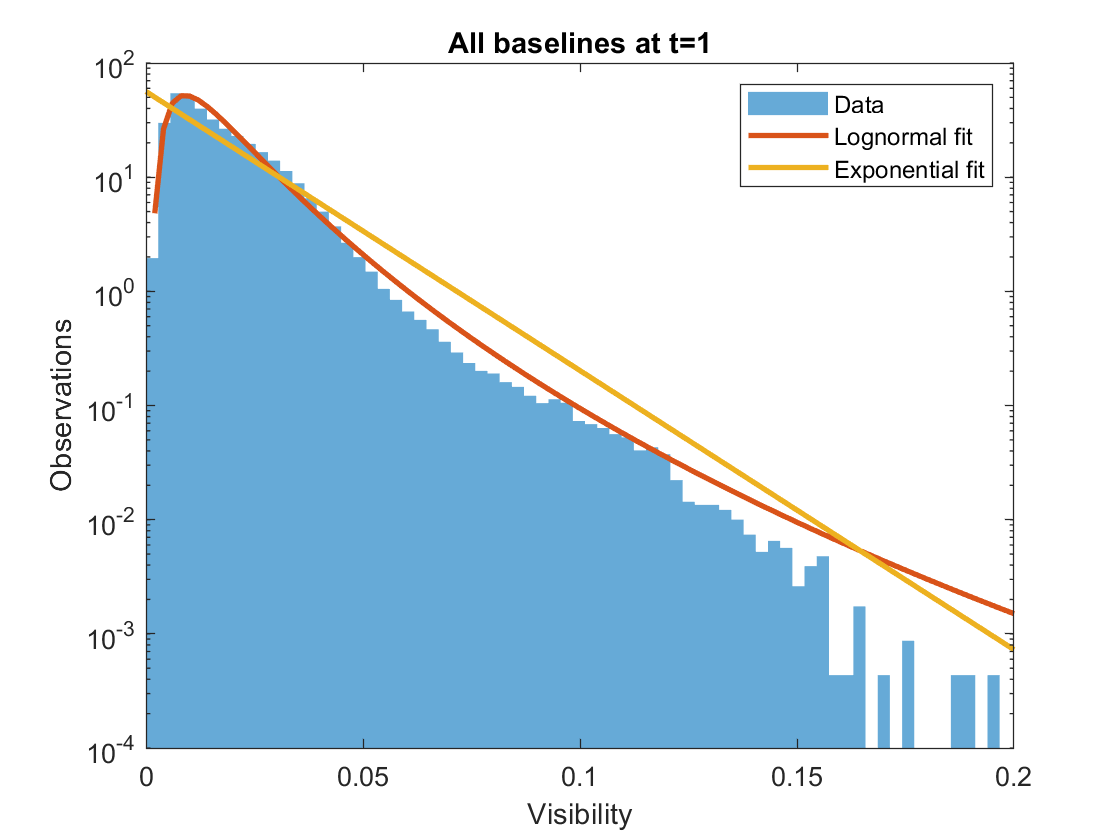

clf;
clean_img_limited = clean_img(:, 180:800);
cap = 0.2;
bkg = clean_img_limited(clean_img_limited < cap);
histogram(bkg, 70, 'EdgeColor',"none", 'Normalization', 'pdf'), hold on;
bkg_v = reshape(bkg(bkg > 0), 1, [])';

PDnorm = fitdist(bkg_v, 'Normal');
PDlogn = fitdist(bkg_v, 'Lognormal');
PDexp = fitdist(bkg_v, 'Exponential');

xs = linspace(0, cap, 100);
logn_ys = lognpdf(xs, PDlogn.mu, PDlogn.sigma);
exp_ys = exppdf(xs, PDexp.mu);
plot(xs, [logn_ys; exp_ys], 'linewidth', 2);
set(gca, 'YScale', 'log')
xlim([0 cap])
%ylim([1e-6, 10])
ylabel('Observations')
xlabel('Visibility')
title('All baselines at t=1')
legend('Data', 'Lognormal fit', 'Exponential fit')

Now the background data seems to follow a lognormal trend. (The normal fit was removed for simplicity, and the exponential fit does not account for the curvature near 0 as well as the concave nature of the plot.)

Using this data, we can now find the signal strength needed for an event with 5 sigma significance:

p_norm = normcdf(-5, 0, 1)

p_norm = 2.8665e-07

mu = PDlogn.mu;
sigma = PDlogn.sigma;
threshold = icdf('Lognormal', 1-p_norm, mu, sigma)

threshold = 0.4247

A visibility amplitude of 0.4247 is large enough to be a 5-sigma event. Note that this threshold is highly dependent on the parameters of the lognormal fit, and that slight variations of these parameters will yield very different thresholds for significant events.

### Problem 2

Now we will "inject" a signal into our background data and see what we observe. To do this, we will change random data points from the background distribution (about 10% of the points) to "signal strength", a strength of around 20 sigma. 

indices = (randi(10, [1, length(bkg)]) < 2);
signal = threshold * 4

signal = 6.9775

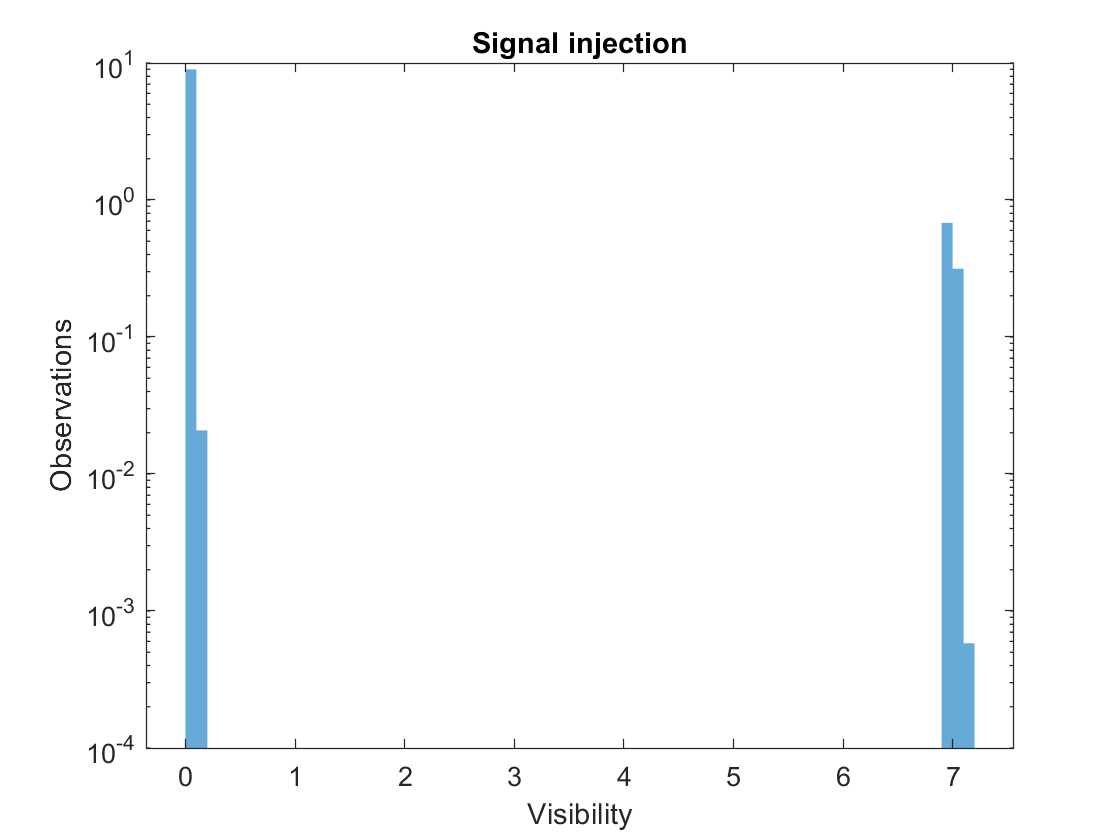

signal_injection = signal .* indices;

clf;
histogram(bkg' + signal_injection, 'EdgeColor',"none", 'Normalization', 'pdf')
set(gca, 'YScale', 'log')
ylabel('Observations')
xlabel('Visibility')
title('Signal injection')

The original background distribution can be seen on the left, ranging from 0 to 0.2. However, we now see an additional distribution on the right, which appears to be very similar to the original distribution.

This makes sense; if we take a random sample of points from the original distribution and scale them up by a constant number, we will get two distributions with smaller amplitudes. By plotting these distributions on a linear scale, we can see that the new distribution is ~10% as large as the original distribution:

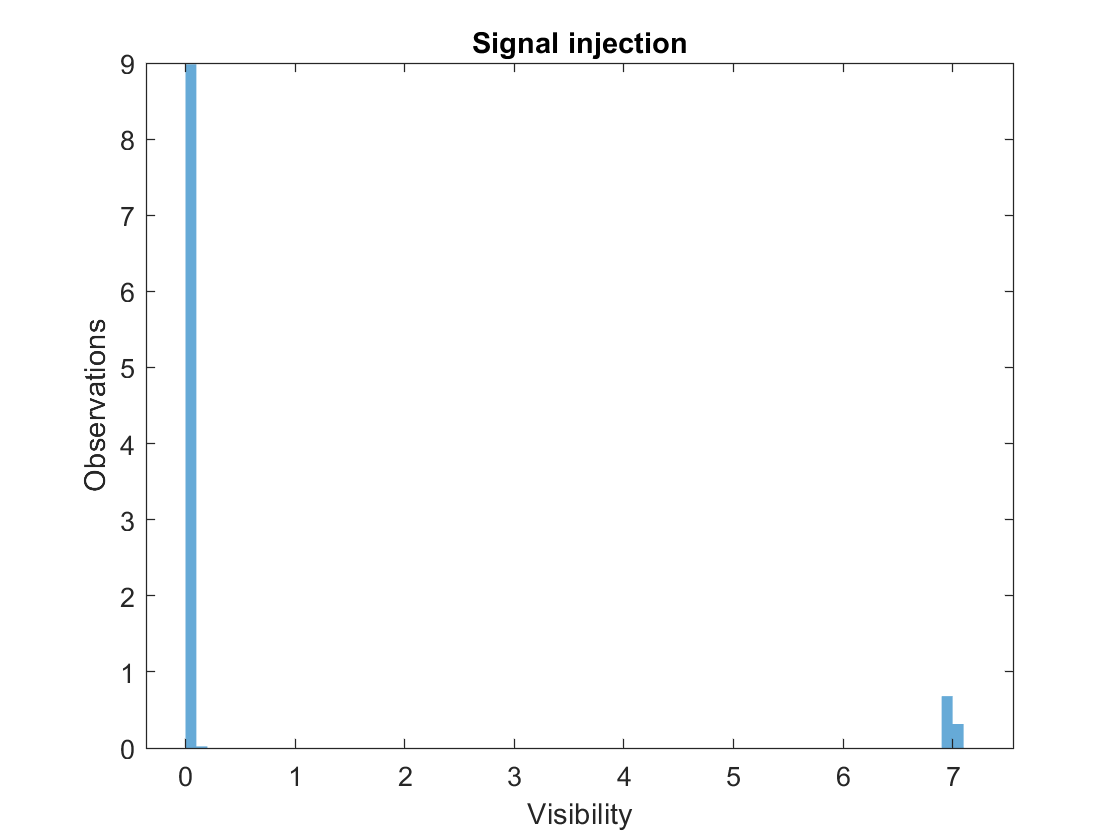

clf;
histogram(bkg' + signal_injection, 'EdgeColor',"none", 'Normalization', 'pdf')
ylabel('Observations')
xlabel('Visibility')
title('Signal injection')

### Problem 2

p_norm = normcdf(-8, 0, 1)

p_norm = 6.2210e-16

signal = icdf('Lognormal', 1-p_norm, mu, sigma)

signal = 28.8290

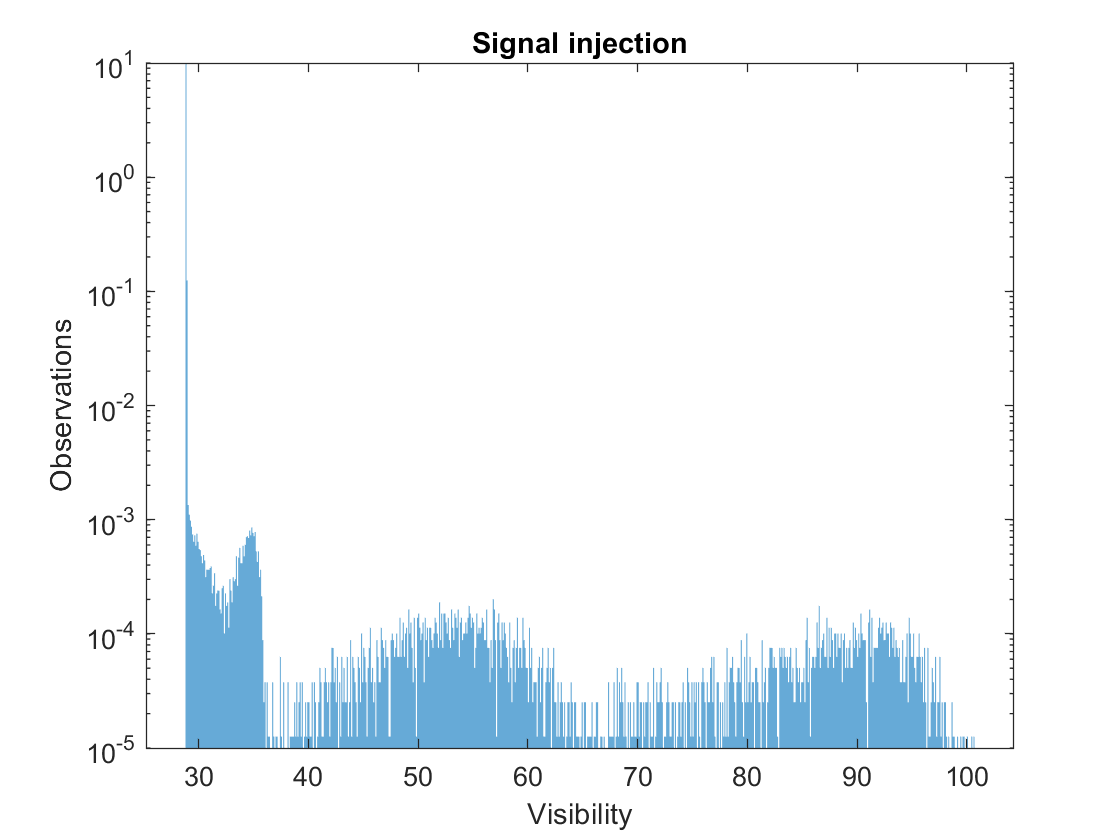

indices = (randi(10, [1326, 600]) < 11);
signal_injection = signal .* indices;
data_array = clean_img(:, 201:800);
clf;
histogram(data_array + signal_injection, 'EdgeColor',"none", 'Normalization', 'pdf')
set(gca, 'YScale', 'log')
ylabel('Observations')
xlabel('Visibility')
title('Signal injection')

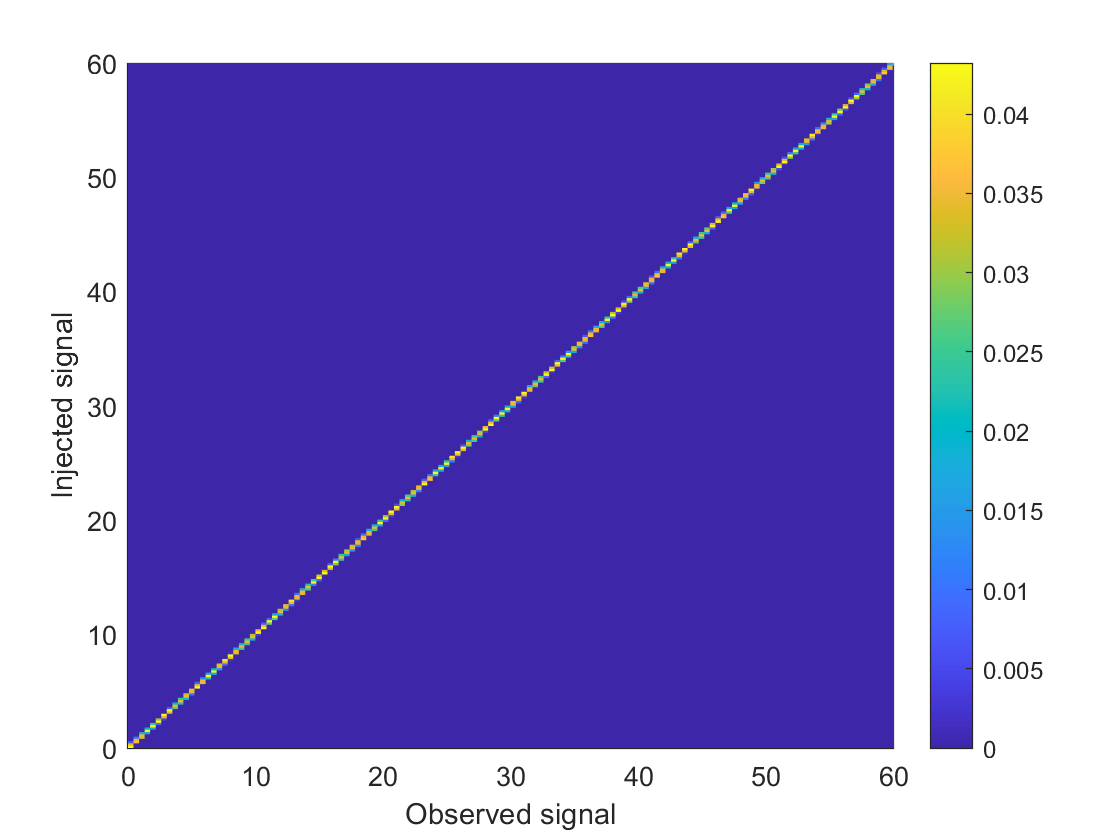

s_lim = 60;
signal_suite = linspace(0, s_lim, 1326);
[~, signal_array] = meshgrid(signal_suite);

noise = indices .* data_array;
obssignal = noise + signal_array(1:1326, 1:600);

clf;
h = histogram2(obssignal,signal_array(1:1326, 1:600), 300,'DisplayStyle','tile','ShowEmptyBins','on', 'Normalization', 'pdf');
xlabel('Observed signal');
ylabel('Injected signal');
axis([0 s_lim 0 s_lim])
c = colorbar;